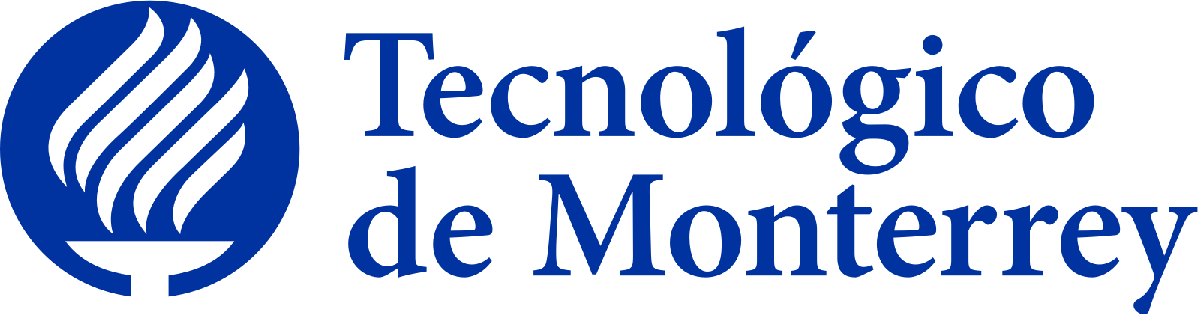

Instituto Tecnológico y de Estudios Superiores de Monterrey

Campus Ciudad de México  

# ** Campos eléctricos asimétricos con Matlab.**

## ***Entrega final.***

Equipo 1.

 Alexa Serrano Negrete - A01654063

Victor Miguel Ramos Catlin - A01660323

Isabel Cristina Valdés Luevanos - A01025802

Octavio Augusto Alemán Esparza - A01660702

Luis Ernesto Ladrón de Guevara González - A01654419 

Modelación Computacional de Sistemas Eléctricos

Dr. Víctor Robledo, Dr. Yoel Ledo, y Dr. Martín Molina

Abril 2021.

## Resumen.

    El presente escrito consta del análisis metodológico y de resultados de la segunda etapa de un proyecto a cinco semanas. El objetivo general que engloba a todo el proyecto es *calcular* y *graficar* campos eléctricos no uniformes como los utilizados en dielectroforesis para el diagnóstico de la malaria. El objetivo específico de esta fase es *representar* el campo vectorial generadopor dos barras asimétricas en cada punto del plano cartesiano dentro de un rango predeterminado. Durante el periodo de trabajo, se utilizó como herramienta principal *MATLAB*. Siendo así, este escrito refleja el trabajo desarrollado durante las últimas dos semanas.

    Este proyecto brinda dos funciones. La primera refleja una optimización hecha al código de la primera etapa del proyecto. Esta no solo mejora la eficacia, sino que también disminuye el tiempo de elaboración del campo eléctrico entre dos partículas específicas. La segunda función es la que se evalúa en esta entrega. Su propósito es generar el campo eléctrico de un dipolo tomando en cuenta la distancia entre las barras a generar simétricas al orígen. 

***Palabras clave: Campo eléctrico, campo vectorial, dipolo, sistemas eléctricos.***

## **Abstract.**

    This project consists of the methodological and results analysis of the second stage of a five-week project. The general objective that encompasses the entire project is to calculate and graph non-uniform electric fields such as those used in dielectrophoresis for the diagnosis of malaria. The specific objective of this phase is to represent the vector field generated by two uneven bars at each point of the Cartesian plane within a predetermined range. During the work period, *MATLAB* was used as the main tool. Thus, this writing reflects the work carried out during the last two weeks.

    This project provides two functions. The first reflects an optimization made to the code from the first stage of the project. This not only improves the efficiency, but also decreases the time to build the electric field between two specific particles. The second function is the one that is evaluated in this installment. Its purpose is to generate the electric field of a dipole taking into account the distance between the bars to be generated symmetrical to the origin.

***Key words: Dipole, electric field, electrical systems, vector field.***

## **Antecedentes.**

    En la primera etapa del reto se calculó el campo eléctrico de un dipolo puntual utilizando MATLAB. Se aplicó la ley de Coulomb para calcular el campo total producido por una carga puntual, resultando en un código que encuentra los campos que se generan entre cada una de las posibles cargas, mientras las grafica. En esta etapa se aplicó el principio de superposición para el cálculo de las componentes $E_x$ y $E_y$. Posteriormente, se llevó a cabo el cálculo del campo eléctrico total $E_{\mathrm{total}}$ en 2D en un punto $P$ del plano producido por el dipolo. 

    Se llevaron a cabo dos casos de prueba, en los rangos de $-10$ a $10$ y de $-5$ a $5$, donde el código generó un espacio bidimensional. En esta etapa, el código no tenía un funcionamiento óptimo, pues más allá de ser lento, tomaba muchas líneas en el cálculo innecesario del ángulo del campo. Por lo tanto, al desarrollar la segunda generación del código fue importante deshacernos de lo innecesario y explicar detalladamente como funciona para evitar confusión.

## **Introducción.**

    La malaria es una enfermedad parasitaria que involucra fiebres altas, escalofríos, síntomas similares a los de la gripe y anemia (MedilinePlus, n.d.). Es causada por el piquete de la hembra de un mosquito infectado. Los síntomas tardan entre diez y quince días en aparecer y puede causar síntomas parecidos a los de una gripe además de fiebre, vómitos, diarrea e ictericia (Secretaría de Gobierno, 2021). La gravedad de esta enfermedad radica en que tan solo en el año 2019 (OMS, 2020) la cifra de contagios de malaria fue estimada en 229 millones a nivel mundial, de los cuales, cerca de 409 000 casos, desafortunadamente terminaron en decesos. Lo que es aún peor, es que el grupo más vulnerable ante la malaria son los niños menores de 5 años. En el mismo año, 2019, 274 000 de los decesos, es decir, cerca de un 67% del total, fueron de niños.

    Acorde al mismo portal de la OMS (2020), es importante mencionar también que el 94% de los casos de malaria y decesos causados por ella a nivel mundial se concentran tan solo en África. Sin embargo, la enfermedad se encuentra también en otras regiones principalmente con climas tropicales en donde haya presencia de mosquitos. En ese sentido, regiones de Asia, Oceanía, Latinoamérica y Sudamérica también se ven afectadas por esta enfermedad. La Fundación iO, encargada de hablar sobre enfermedades, medicina y viajes, estableció en 2019 que en el año previo en México se detectaron 736 casos. La enfermedad está presente principalmente en Chiapas, Campeche, Durango, Jalisco, Nayarit, Quintana Roo, San Luis Potosí, Sinaloa, Sonora y Tabasco.

    Uno de los métodos de detección es la *dielectroforesis.* Esto se refiere a "un movimientode las partículascausadopor los efectosde polarizaciónenun campo eléctricono uniforme" (química.es, n.d.). A pesar de que este método de tratado es el que lleva al desarrollo del proyecto, no es el más óptimo para la detección por diversas situaciones. Una de las más importantes es por la falta de acceso a esta tecnología por las personas que se enferman, puesto que, desafortunadamente, los países en vías de desarrollo no tienen el acceso universal garantizado.

## **Marco Teórico.**

### ***Campos eléctricos.***

    La tercera edición de *Physics for Scientists and Engineers* (Serway, s.f.) introduce al campo eléctrico aclarando qué es acción a distancia, siendo esta la acción de la fuerza que ocurre aún cuando no exista contacto físico entre los objetos. El ejemplo más claro de esto es la fuerza gravitacional que ejerce una masa sobre la otra. En 1821, Michael Faraday junto con algunos otros matemáticos y físicos conciben el concepto de campo. La definición del creador del portal de consulta  *ingenieriaelectrica.org*, dicta que un campo eléctrico es “Un espacio de cualquier tamaño cuyas propiedades han sido alteradas o modificadas debido al hecho de añadir una carga” (de la Cruz, 2019). 

*    Physics for Scientists and Engineers*, mencionado previamente, establece que “La región del espacio que rodea a una carga u objeto cargado (la fuente de carga) tiene una propiedad que se conoce como campo eléctrico. Esta carga crea un campo eléctrico $E$ en todo el espacio, y este campo ejerce una fuerza $F_e$ sobre cualquier otra carga u objeto cargado en la posición de esta segunda carga. [...] Cuando otro objeto también cargado entra en la región de un campo eléctrico, una fuerza $F$ actúa sobre él” (Serway, s.f.).

Es aquí donde entra la ley de Coulomb. En el área de la física, esta ley se utiliza para calcular la fuerza electrostática de atracción o repulsión entre dos cargas, así como la distancia entre ambas. Dicha ley se representa de la siguiente manera: 


$$F_e =k\cdot \frac{q_1 q_2 }{r^2 }$$


    Donde $F$ representa la fuerza eléctrica en Newtons, $k$ la constante de Coulomb cuyo valor es de $9\times {10}^9 \frac{{N\cdot m}^2 }{C^2 }$, $q$ el valor de las cargas eléctricas en Coulomb, y $r$ la distancia que separa a las dos cargas en metros. 

    Retomando el concepto de campo eléctrico, el campo eléctrico es un vector que describe la condición en el espacio creada por un sistema de cargas puntuales. Por tanto, se puede entender como una función vectorial de posición.

### ***Principio de Superposición.***

    El principio de superposición permite descomponer un problema lineal en problemas más sencillos. En el caso de este proyecto, el campo eléctrico formado por barras puede ser pensado como una generalización de un campo eléctrico formado por un dipolo eléctrico. Para cada partícula que se encuentre en las barras cargadas positiva o negativa, habrá una partícula prueba en el plano que genere un campo con componentes $x$ y $y$, de forma que la suma de todos los componentes correspondientes para cada partícula sea representada por un vector resultante 


$$\overset{\longrightarrow }{E} =<E\;\cos \;\theta ,E\;\sin \;\theta >$$


    De forma que


$$E=k_e \cdot \frac{Q}{r^2 }$$


    Donde $k_e$ es la constante de Coulomb, $Q$ la carga que genera el campo,$r$ la distancia entre la carga prueba y la dicha carga. Por geometría se puede decucir que


$$\sin \;\theta =\frac{c\ldotp o\ldotp }{\mathrm{hip}}$$



$$\cos \;\theta =\frac{c\ldotp a\ldotp }{\mathrm{hip}}$$


    Pero para toda partícula prueba 


$$P_0 =\;<x,\;\;y>\;$$


    Donde $\mathrm{abs}\left(y\right)$ será la distancia vertical que corresponde al cateto opuesto del ángulo, mientras que el cateto adjacente depende de si se hace con respecto a la particula positiva o negativa. Para la negativa, 


$$c\ldotp a\;=x-a\;$$


    Para la positiva,


$$c\ldotp a\;=a+x$$


    Mientras que la hipotenusa es simplemente la distancia entre la $P_0$ y la carga.


$$\textrm{hip}\;=r=\sqrt{{\left(a+x\right)}^2 +y^2 }$$


    Por tanto, para cargas positivas


$$\overset{\longrightarrow }{E} =\left\langle E\frac{a+x}{\sqrt{{\left(a+x\right)}^2 +y^2 }},\;E\frac{\textrm{abs}\left(y\right)}{\sqrt{{\left(a+x\right)}^2 +y^2 }}\right\rangle =\left\langle k_e \frac{Q\left(a+x\right)}{{\left({\left(x-a\right)}^2 +y^2 \right)}^{\frac{3}{2}} },\left\langle k_e \frac{Q\;\textrm{abs}\left(y\right)}{{\left({\left(x-a\right)}^2 +y^2 \right)}^{\frac{3}{2}} }\right\rangle \right.$$


    Y para negativas,


$$\overset{\longrightarrow }{E} =\left\langle E\frac{x-a}{\sqrt{{\left(x-a\right)}^2 +y^2 }}\;,\;E\frac{\mathrm{abs}\left(y\right)}{\sqrt{{\left(x-a\right)}^2 +y^2 }}\;\right\rangle \;=\left\langle \;k_e \frac{Q\left(\;x-a\right)}{{\left({\left(x-a\right)}^2 +y^2 \right)}^{\frac{3}{2}} }\;,k_e \frac{Q\;\mathrm{abs}\left(y\right)}{{\left({\left(x-a\right)}^2 +y^2 \right)}^{\frac{3}{2}} }\;\right\rangle$$


## **Metodología.**

    Para la realización de este reto, únicamente se utilizó la herramienta computacional de de *Matlab.* Para el desarrollo objetivo del proyecto se llevaron a cabo los cálculos matemáticos expuestos a continuación para conseguir los componentes en $y$ y $x$ para graficar el campo del dipolo.

    El código consiste de dos funciones principales. La primera que se va a explicar es la adaptación del código de la primera etapa. La segunda va a generar un dipolo a la misma distancia entre las barras simétricas al origen.

    Por formato de MATLAB, las gráficas se añaden en este punto del documento.

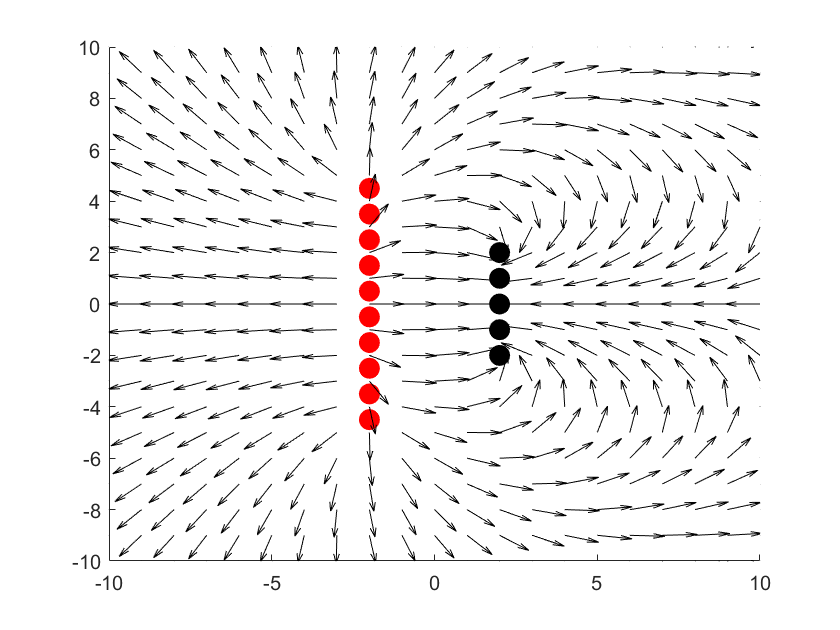

close all; clear; clc;

genDipoloBar();

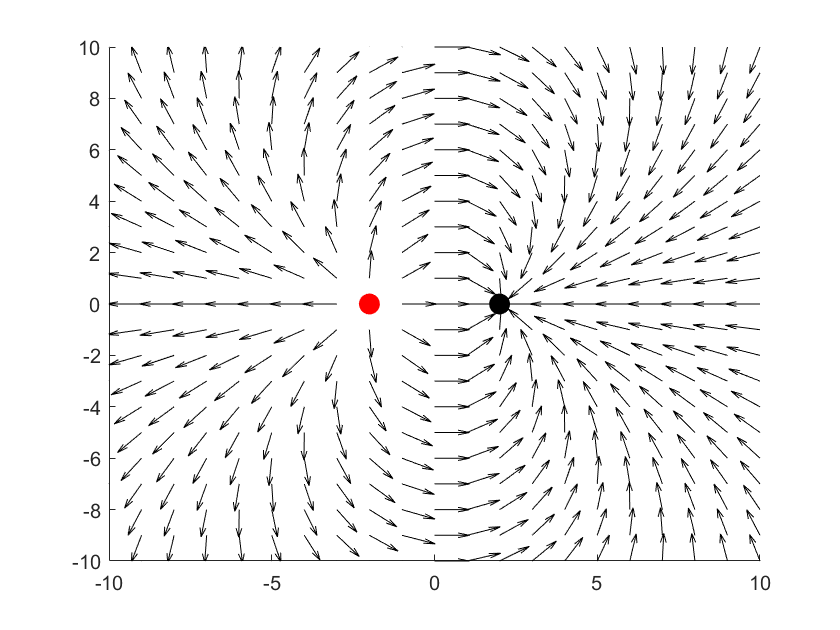

genDipoloPar();

### *Función uno.*

    La función se escribe como

`function genDipoloPar(k, a, scale, delta, minval, maxval, qpos, qneg)`

    `genDipoloPar` genera un dipolo tomando en cuenta la posición simétrica `a` de las partículas con respecto al origen. Por predeterminado, se asignan los siguientes valores a la función, a saber:

`k (1,1) double = 1`

`a (1,1) double = 2`

`scale (1,1) double = 1`

`delta (1,1) double = 1`

`minval (1,1) double = -10`

`maxval (1,1) double = 10`

`qpos (1,1) double = 1`

`qneg (1,1) double = -1`

    Donde `K` es la constante para la intensidad del campo electrico. Si `k == 0` entonces `k` será el valor de la constante de Coulomb.

`  a` es la distancia entre las barras, mientras que `a/2` será la distancia simétrica desde ambas barras al origen.

    `minval` será el valor de $x$, y mínimo que genera el espacio bidimensional donde se encuentra el campo.

    `maxval` será el valor de $x$, y máximo que genera el espacio bidimensional donde se encuentra el campo.

    Con `scatter` se pondrán los puntos y se les dará el formato necesario (es decir, color de borde y relleno) tanto con la carga negativa como con la positiva. Con los `for` se generan los vectores dentro de la malla que ya se generaró con la función `meshgrid`. Dentro de los `for` se insertan las ecuaciones de los componentes en `y` y en `x`.

    El código de esta primera función se observa de la siguiente manera, a saber:

function genDipoloPar(k, a, scale, delta, minval, maxval, qpos, qneg)
arguments   
    k (1,1) double = 1
    a (1,1) double = 2
    scale (1,1) double = 0.8
    delta (1,1) double = 1
    minval (1,1) double = -10
    maxval (1,1) double = 10
    qpos (1,1) double = 1
    qneg (1,1) double = -1
end

% Dibujo del dipolo
if k == 0
    k = 8.99e9;
end

% Grafica el primer punto en -a (particula positiva)
qposplt = scatter([-a], [0]);
qposplt.SizeData = 100;
qposplt.MarkerFaceColor = 'r'; % El color del relleno de los puntos
qposplt.MarkerEdgeColor = 'r'; % El color del marco de los puntos 
hold on;

% Grafica el segundo punto en a (particula negativa)
qnegplt = scatter([a], [0]);
qnegplt.SizeData = 100;
qnegplt.MarkerFaceColor = 'k'; % El color del relleno de los puntos
qnegplt.MarkerEdgeColor = 'k'; % El color del marco de los puntos
axis([minval maxval minval maxval]);

malla_x = minval:delta:maxval;
malla_y = minval:delta:maxval;

% Meshgrid
[x, y] = meshgrid(malla_x, malla_y);

% Ecuaciones x
E1x = ((k*(qpos).*(a+x))./((a+x).^2 + y.^2).^(3/2));
% Componente x con respecto a la positiva
E2x = ((k*(qneg).*(x-a))./((x-a).^2 + y.^2).^(3/2));
% Componente x con respecto a la negativa

% Ecuaciones y
E1y = ((k*(qpos).*y)./((a+x).^2 + y.^2).^(3/2));
% Componente y con respecto a la positiva
E2y = ((k*(qneg).*y)./((x-a).^2 + y.^2).^(3/2));
% Componente y con respecto a la negativa

Ex = (E1x + E2x); % Suma el total de cada componente x segun su particula
Ey = (E1y + E2y); % Suma el total de cada componente y segun su particula
Module = sqrt(Ex.^2 + Ey.^2); % Se encuentra el modulo para poder graficar 
% la magnitud del campo normalizada segun su vector unitario.
quiver(x, y, Ex./Module, Ey./Module, scale, 'Color','k', 'linewidth', 0.5);
hold off
end

### *Función dos.*

    La función se escribe como

`function genDipoloBar(k, a, lenBarPos, lenBarNeg, scale, delta, minval, maxval, qpos, qneg)`

    `genDipoloBar` genera un dipolo tomando en cuenta la distancia entre las barras a generar simétricas al origen. Por predeterminado, se asignan los siguientes valores a la función. Por predeterminado, se asignan los siguientes valores a la función, a saber:

`k (1,1) double = 1`

`a (1,1) double = 2`

`lenBarPos (1,1) double = 1`

`lenBarNeg (1,1) double = 1`

`scale (1,1) double = 1`

`delta (1,1) double = 1`

`minval (1,1) double = -10`

`maxval (1,1) double = 10`

`qpos (1,1) double = 1`

`qneg (1,1) double = -1`

    Donde `lenBarPos` será la cantidad de cargas en la barra positiva separadas por `delta`, y `lenBarNeg` será la cantidad de cargas en la barra negativa separadas por `delta`.

    El código de esta primera función se observa de la siguiente manera, a saber:

function genDipoloBar(k, a, lenBarPos, lenBarNeg, scale, delta, minval, maxval, qpos, qneg)

arguments   
    k (1,1) double = 1
    a (1,1) double = 2 % Mitad de las distancias entre las barras
    lenBarPos (1,1) double = 10
    lenBarNeg (1,1) double = 5
    scale (1,1) double = 0.8
    delta (1,1) double = 1
    minval (1,1) double = -10
    maxval (1,1) double = 10
    qpos (1,1) double = 1
    qneg (1,1) double = -1
end

% Dibujo del dipolo
if mod(lenBarPos, 2) == 0 % Par
    posYChar = -(lenBarPos-1)/2:delta:(lenBarPos-1)/2;
else % Impar
    posYChar = -(lenBarPos-1)/2:delta:(lenBarPos-1)/2;
end

if mod(lenBarNeg, 2) == 0 % Par
    negYChar = -(lenBarNeg-1)/2:delta:(lenBarNeg-1)/2;
else % Impar
    negYChar = -(lenBarNeg-1)/2:delta:(lenBarNeg-1)/2;
end

posXChar = ones(1, length(posYChar)) .* (-a);
negXChar = ones(1, length(negYChar)) .* (a);

% Graficar el primer punto en -a (particula positiva)
qposplt = scatter(posXChar, posYChar);
qposplt.SizeData = 100;
qposplt.MarkerFaceColor = 'r'; % El color del relleno de los puntos
qposplt.MarkerEdgeColor = 'r'; % El color del marco de los puntos
hold on;

% Graficar el segundo punto en a (particula negativa)
qnegplt = scatter(negXChar, negYChar);
qnegplt.SizeData = 100;
qnegplt.MarkerFaceColor = 'k'; % El color del relleno de los puntos
qnegplt.MarkerEdgeColor = 'k'; % El color del marco de los puntos
axis([minval maxval minval maxval]); 

if k == 0
   k = 8.99e9;
end

malla_x = minval:delta:maxval;
malla_y = minval:delta:maxval;

% Meshgrid
[x, y] = meshgrid(malla_x, malla_y);

% (E1x (desde carga pos)) = k * q / r^2 * cos(th) pero cos th = C.A / h = 
% c.a / r => k*q / r^3 pero r = sqrt((a + x)^2 + (0 - y) ^ 2 {Sean a, n}
E1x = 0; E1y = 0; E2x = 0; E2y = 0;


for i = 1:lenBarPos % Itera por cada una de las cargas en la barra positiva y guarda
    % la suma total del componente x y y para dicha barra 
    E1x = E1x + ((k*(qpos).*(a+x))./((a+x).^2 +  (y - posYChar(i)).^2).^(3/2));
    % Componente x con respecto a la positiva
    E1y = E1y + ((k*(qpos).*(y - posYChar(i)))./((a+x).^2 + (y - posYChar(i)).^2).^(3/2));
    % Componente y con respecto a la positiva
end

for i = 1:lenBarNeg % Itera por cada una de las cargas en la barra negativa y guarda
    % la suma total del componente x y y para dicha barra 
    E2x = E2x + ((k*(qneg).*(x-a))./((x-a).^2 + (y - negYChar(i)).^2).^(3/2));
    % Componente x con respecto a la negativa
    E2y = E2y + ((k*(qneg).*(y - negYChar(i)))./((x-a).^2 + (y - negYChar(i)).^2).^(3/2));
    % Componente y con respecto a la negativa
end

Ex = (E1x + E2x); % Suma el total de cada componente x segun su particula
Ey = (E1y + E2y); % Suma el total de cada componente y segun su particula
Module = sqrt(Ex.^2 + Ey.^2); % Se encuentra el modulo para poder graficar la magnitud
% del campo normalizada segun su vector unitario
quiver(x, y, Ex./Module, Ey./Module, scale, 'Color','k', 'linewidth', 0.5); 
% quiver(x, y, Ex, Ey, scale, 'Color','k', 'linewidth', 0.5); 
hold off
end

## **Análisis de Resultados.**

    La primera función otorgó finalmente un campo de dos partículas individuales centradas en el eje. Es muy importante mencionar que se logró corregir el funcionamiento del código, disminuyendo de 157 líneas para el primer código a solo 54, otorgando un resultado no solo más acertado, sino también más rápido en su cálculo. Por otra parte, la segunda función generó barras perfectamente simétricas, donde no afecta si el dato ingresado es par o impar. 

    Ambos códigos son igual de funcionales y tienen distintas herramientas dentro del código, utilizando ciclos `for`, `if` y `meshgrid` como herramientas para el diseño de las mallas, así como para el cálculo del campo eléctrico. El código entrega campos simétricos y asimétricos y ofrece funciones replicables con variables que se pueden modificar o mantener a gusto del usuario.

## **Conclusiones.**

    Este proyecto, más allá de brindar herramientas computacionales, permitió visualizar la forma de empleo de la programación en la vida real. Se lograron cumplir los objetivos de manera óptima, y el funcionamiento del código no solo fue eficiente, sino que también estético y replicable. Se juntaron competencias de todos los niveles y características, pues el trabajo en equipo así como la comunicación asertiva fueron claves para el desarrollo objetivo del proyecto. Incorporar las habilidades de cada miembro del equipo permitió que se lograra este proyecto. Se espera que este código funcione en un futuro a más personas como herramienta de referencia, y se espera poder continuar trabajando en conjunto para ayudar a resolver problemáticas sociales de alto impacto con tecnología.

## Referencias.

U.S. National Library of Medicine. (2020). Malaria. abril 29, 2021, de MedlinePlus. Sitio web: [https://medlineplus.gov/spanish/malaria.html](https://medlineplus.gov/spanish/malaria.html) 

OMS. (2020). Paludismo. abril 29, 2021, de Organización Mundial de la Salud. Sitio web: [https://www.who.int/es/news-room/fact-sheets/detail/malaria](https://www.who.int/es/news-room/fact-sheets/detail/malaria) 

U.S. National Library of Medicine. (2021). Pruebas de malaria. abril 29, 2021, de MedlinePlus. Sitio web: [https://medlineplus.gov/spanish/pruebas-de-laboratorio/pruebas-de-malaria/#:~:text=Si%20sospecha%20que%20usted%20tiene,tubo%20de%20ensayo%20o%20frasco.](https://medlineplus.gov/spanish/pruebas-de-laboratorio/pruebas-de-malaria/#:~:text=Si%20sospecha%20que%20usted%20tiene,tubo%20de%20ensayo%20o%20frasco.) 

Fundación iO. (2019). MALARIA EN MÉXICO. abril 29, 2021, de Fundación iO Sitio web: [https://fundacionio.com/viajarseguro/paises/mexico/malaria-mexico/](https://fundacionio.com/viajarseguro/paises/mexico/malaria-mexico/) 

R. Serway,; Physics for Scientists and Engineers, Saunders College Publishers, 3rd edition.

De la Cruz, L. (2019). El Campo Eléctrico. Recuperado el 15 de abril del 2021 de [https://ingenieriaelectronica.org/el-campo-electrico-ley-de-faraday-campos-electricos-y-magneticos/](https://ingenieriaelectronica.org/el-campo-electrico-ley-de-faraday-campos-electricos-y-magneticos/)

S. (2020, 17 abril). *Ley de Coulomb*. Significados. https://www.significados.com/ley-de-coulomb/